# Is Game B really rigged against us?

#### Generating the State Transition Matrix for Game B in order to check long term probabilties of bust vs sufficient profit.

addpath ../dablab_files/dablab_repo/
latex_interpreter

Gambler brings $budget$ as initial budget and bets $bet%$ each turn. Leaves if he busts ($0) or if he makes $withdraw$ amount of money.

tic;
budget = 100;
bet = 1;
withdrawMax = 2*budget;
withdrawMin = budget+bet;

withdraw = 200;
numTurns = (withdraw/bet)*1000

numTurns = 200000

% numTurns = 1000;
B = zeros(withdraw/bet+1, withdraw/bet+1);
p_win_b1 = 4/38, p_win_b2 = 27/38 %for rigged games

p_win_b1 = 0.1053

p_win_b2 = 0.7105

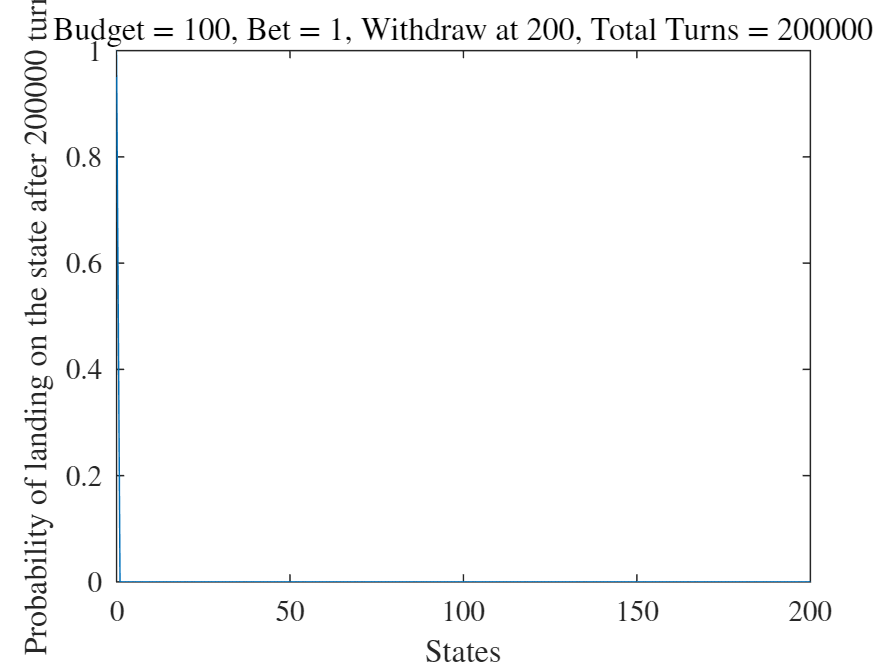

% p_win_b1 = 1/10, p_win_b2 = 3/4 
%for almost fair games as per parrondo's
% paper
M = 3;

for FROMbudget = 0:bet:withdraw
    for TObudget = 0:bet:withdraw
        if FROMbudget == 0
            if TObudget == 0
                B(FROMbudget/bet+1, TObudget/bet+1) = 1;
            end
        elseif FROMbudget == withdraw
            if TObudget == withdraw
                B(FROMbudget/bet+1, TObudget/bet+1) = 1;
            end
        elseif TObudget == FROMbudget - bet
            if mod(FROMbudget, M) == 0
                B(FROMbudget/bet+1, TObudget/bet+1) = 1-p_win_b1;
            else
                B(FROMbudget/bet+1, TObudget/bet+1) = 1-p_win_b2;
            end
        elseif TObudget == FROMbudget + bet
                if mod(FROMbudget, M) == 0
                    B(FROMbudget/bet+1, TObudget/bet+1) = p_win_b1;
                else
                    B(FROMbudget/bet+1, TObudget/bet+1) = p_win_b2;
                end
        end
    end
end

B;

B_inf = B^numTurns;
states = 0:bet:withdraw;
plot(states, B_inf(budget/bet+1, :))
title(strcat("Budget =  ", num2str(budget), ", Bet = ", num2str(bet), ...
    ", Withdraw at ", num2str(withdraw), ...
    ", Total Turns = ", num2str(numTurns)))
% xticks(states)
xlabel('States')
ylabel(strcat(['Probability of landing'  ...
    ' on the state after ', num2str(numTurns), ' turns']));


p_withdraw = B_inf(budget/bet+1, withdraw/bet+1)

p_withdraw = 1.0767e-05

p_bust = B_inf(budget/bet+1, 1)

p_bust = 1.0000

toc;

Elapsed time is 0.074037 seconds.
